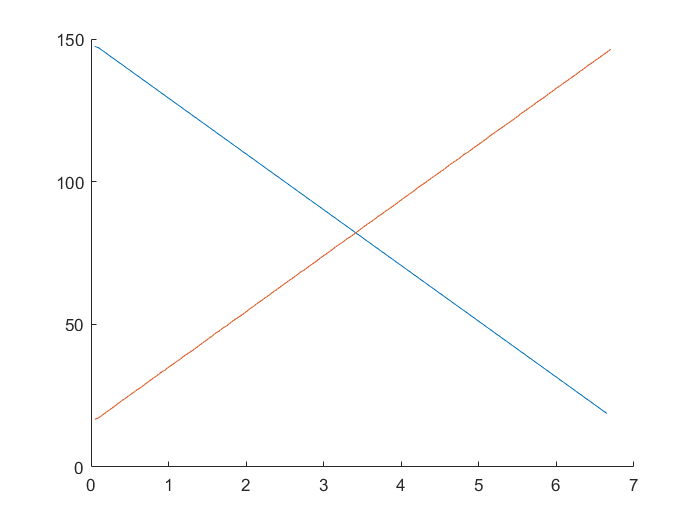

% Matriz combinada con los datos obtenidos reales
tiempo_r = TimeSeconds(1:end-150);
distancia_r = 100*(SonarMeters(151:end) - ParedMeters(151:end));
matriz_combinada_r = cat(2,tiempo_r,distancia_r);
matriz_combinada_v = cat(2,tiempo_v.',distancia_v.');

% Depuración de la data
matriz_depurada_r = depura_matrices(matriz_combinada_r, 0, 6.7);
matriz_depurada_v = depura_matrices(matriz_combinada_v, 0, 6.7);

% Se imprimen muestras
hold on 
plot(matriz_depurada_r(:,1).',matriz_depurada_r(:,2).')
plot(matriz_depurada_v(:,1).',matriz_depurada_v(:,2).')
hold off

function matriz_limpia = depura_matrices(matriz, corte_inicio, corte_final)    
    matriz_limpia = [];
    for i = 1: size(matriz,1)
        if matriz(i,1) > corte_inicio && matriz(i,1) < corte_final
            matriz_limpia = [matriz_limpia; matriz(i,:)];
        end
    end
end